# Unofficial DCASE2021 Task 1A Baseline Using MATLAB

The following example walks through training, deploying, and evaluating an unofficial MATLAB implementation of the DCASE2021 Task 1A baseline.

## Dataset

Download the [TAU Urban Acoustic Scenes 2020 mobile, Development dataset](https://zenodo.org/record/3819968#.YG5TiWRKg2w). The convenience function, `loadDCASEdata`, downloads and unzips the data to your specified location and then loads the data into [`audioDatastore`](https://www.mathworks.com/help/audio/ref/audiodatastore.html) objects.

loc = fullfile(pwd,'DCASE2021-1A-Data');
[adsTrain,adsTest] = loadDCASEdata(loc);

Read a sample from the train set and listen to the audio. Plot the waveform.

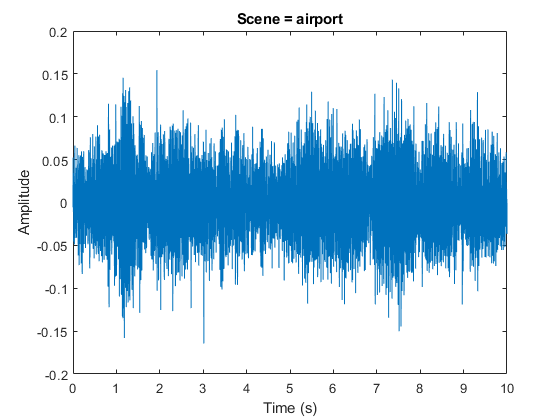

[audioIn,audioInfo] = read(adsTrain);

sound(audioIn,audioInfo.SampleRate)
t = linspace(0,10,numel(audioIn));
plot(t,audioIn)
xlabel('Time (s)')
ylabel('Amplitude')
title("Scene = " + string(audioInfo.Label))

Inspect the label distributions in the train and test sets.

countEachLabel(adsTrain)

ans = 10×2 table
          Label          Count
    _________________    _____

    airport              1393 
    bus                  1400 
    metro                1382 
    metro_station        1380 
    park                 1429 
    public_square        1427 
    shopping_mall        1373 
    street_pedestrian    1386 
    street_traffic       1413 
    tram                 1379 


countEachLabel(adsTest)

ans = 10×2 table
          Label          Count
    _________________    _____

    airport               296 
    bus                   297 
    metro                 297 
    metro_station         297 
    park                  297 
    public_square         297 
    shopping_mall         297 
    street_pedestrian     297 
    street_traffic        297 
    tram                  296 


## Dataset Augmentation

In this example, the dataset is not augmented, following the DCASE official baseline. To learn how to augment the dataset, see [audioDataAugmenter](https://www.mathworks.com/help/audio/ref/audiodataaugmenter.html) and [Acoustic Scene Recognition Using Late Fusion](https://www.mathworks.com/help/audio/ug/acoustic-scene-recognition-using-late-fusion.html).

## Feature Extraction Pipeline

Create an `audioFeatureExtractor` to extract a 40-band magnitude mel spectrogram. The parameters here follow the official baseline, although implementation details vary. You might enhance the baseline by extracting other features as well. For a list of features `audioFeatureExtractor` supports, see [the documentation](https://www.mathworks.com/help/audio/ref/audiofeatureextractor.html).

windowDur = 0.04;
overlapDur = 0.02;
afe = audioFeatureExtractor( ...
    "SampleRate",audioInfo.SampleRate, ...
    "Window",hamming(round(windowDur*audioInfo.SampleRate),"periodic"), ...
    "OverlapLength",round(overlapDur*audioInfo.SampleRate), ...
    "FFTLength",2048, ...
    ...
    'melSpectrum',true);
setExtractorParams(afe,"melSpectrum", ...
    "NumBands",40,"SpectrumType","magnitude");

Convert the datastores to transform datastores that extract the log-mel spectrums of audio that has been scaled so that its max absolute value is 1.

pad = zeros(afe.OverlapLength,1);
adsTrainTransformed = transform(adsTrain, ...
    @(x)log10(((extract(afe,[pad;x]./max(abs(x)))+eps('single')))));
adsTestTransformed = transform(adsTest, ...
    @(x)log10(((extract(afe,[pad;x]./max(abs(x)))+eps('single')))));

Visualize the features extracted from one of the train files.

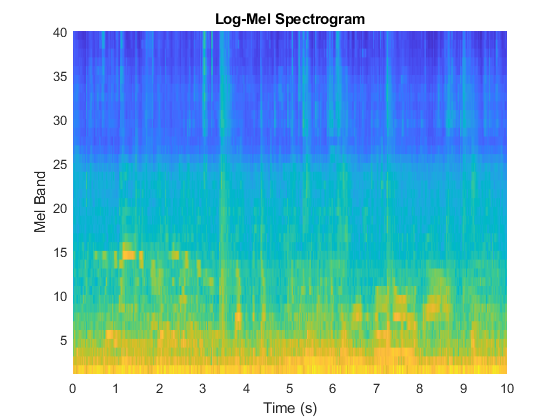

features = read(adsTrainTransformed);
[numHops,numFeatures] = size(features);
t = linspace(0,10,500);
bands = 1:40;
surf(t,bands,features','EdgeColor','none')
xlabel('Time (s)')
ylabel('Mel Band')
zlabel('Magnitude')
title('Log-Mel Spectrogram')
view([0,90])
axis tight

Extract features from the train and test sets.

trainFeatures = gather(tall(adsTrainTransformed));

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).
Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 5 min 31 sec
Evaluation completed in 5 min 32 sec


testFeatures = gather(tall(adsTestTransformed));

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 1 min 10 sec
Evaluation completed in 1 min 10 sec


Split the extracted features so that the features are in the shape *numFeatures*-by-*numHops*-by-1-by-*numFiles*.

testFeatures = permute(testFeatures,[2,1]);
testFeatures = reshape(testFeatures,numFeatures,numHops,1,[]);
trainFeatures = permute(trainFeatures,[2,1]);
trainFeatures = reshape(trainFeatures,numFeatures,numHops,1,[]);

Use the train set to determine the population mean and standard deviation.

mu = mean(trainFeatures(:),1);
STD = std(trainFeatures(:),0,'all');

Standardize the train and test sets.

trainFeatures = (trainFeatures - mu)./STD;
testFeatures = (testFeatures - mu)./STD;

For convenience, create variables for the test and train labels.

testLabels = adsTest.Labels;
trainLabels = adsTrain.Labels;

## Network Definition

Define the network architecture as defined in the DCASE baseline.

layers = [ 
    imageInputLayer([numFeatures,numHops],'Normalization',"none")
    
    convolution2dLayer(7,16,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(7,16,"Padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([5,5],'Stride',5)
    dropoutLayer(0.3)
    
    convolution2dLayer(7,32,"Padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([4,100],'Stride',4)
    dropoutLayer(0.3)
    
    fullyConnectedLayer(100)
    reluLayer
    dropoutLayer(0.3)
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ]

layers =   20×1 Layer array with layers:

     1   ''   Image Input             40×500×1 images
     2   ''   Convolution             16 7×7 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   Convolution             16 7×7 convolutions with stride [1  1] and padding 'same'
     6   ''   Batch Normalization     Batch normalization
     7   ''   ReLU                    ReLU
     8   ''   Max Pooling             5×5 max pooling with stride [5  5] and padding [0  0  0  0]
     9   ''   Dropout                 30% dropout
    10   ''   Convolution             32 7×7 convolutions with stride [1  1] and padding 'same'
    11   ''   Batch Normalization     Batch normalization
    12   ''   ReLU                    ReLU
    13   ''   Max Pooling             4×100 max pooling with stride [4  4] and padding [

Call `analyzeNetwork` to validate the network and visualize the layers.

analyzeNetwork(layers)

## Training Options

Define the same training parameters as in the official DCASE baseline. The only known difference in the parameters in this example is that we use a much larger minibatch size.

miniBatchSize = 256; % Modified from 16 in the official baseline.
opts = trainingOptions("adam", ...
    'LearnRateSchedule',"piecewise", ... % Modified from none in the official baseline.
    'LearnRateDropPeriod',100, ... % Modified from official baseline.
    'LearnRateDropFactor',0.5, ... % Modified from official baseline.
    'MaxEpochs',120, ... % Modified from 200 in the official baseline.
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle',"every-epoch", ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',{testFeatures,testLabels}, ...
    'ValidationFrequency',2*floor(numel(trainLabels)/miniBatchSize));

## Train

Train the network.

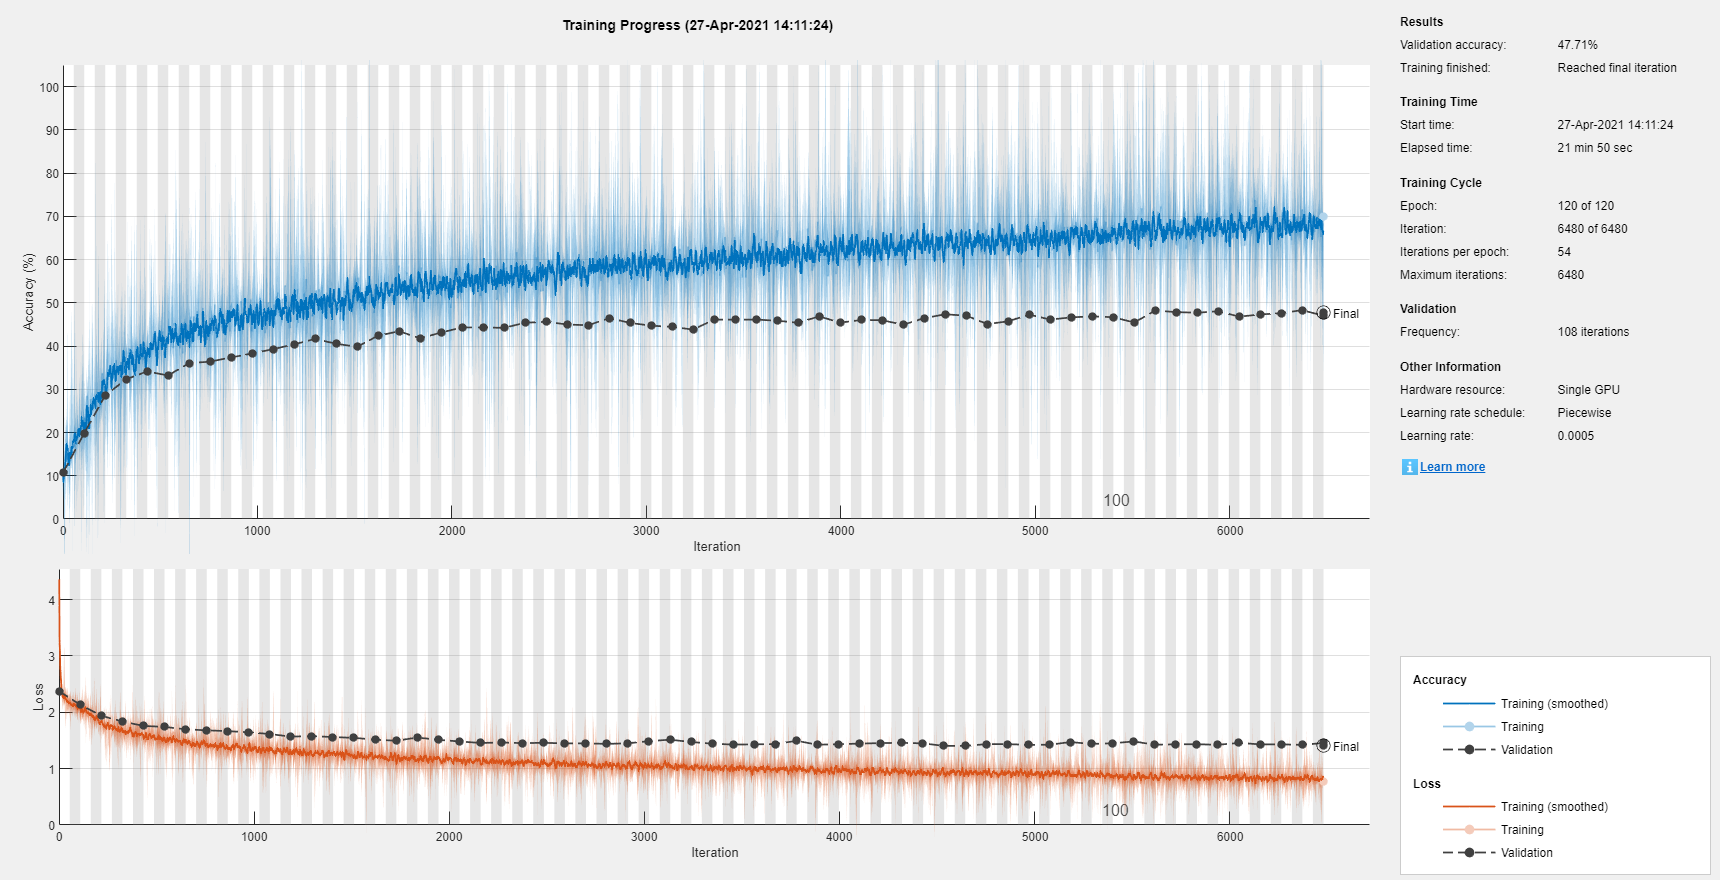

[net,netInfo] = trainNetwork(trainFeatures,trainLabels,layers,opts);

Save the network.

save('acoustSceneClassificationSmallNetwork.mat','net')

## Evaluation

Call `classify` to make predictions on the test feature set.

predictions = classify(net,testFeatures);

Create a confusion matrix to visualize the performance of the test set.

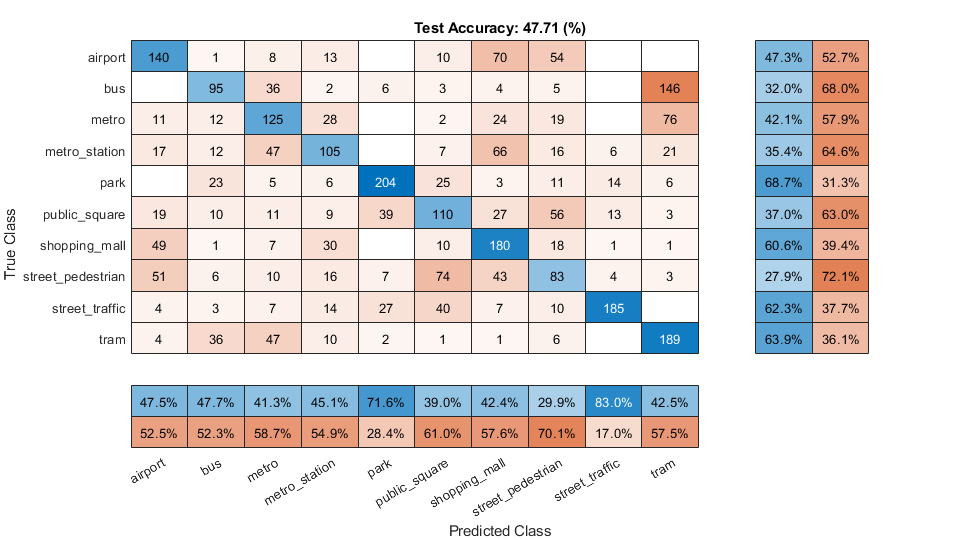

trueLabels = categorical(testLabels);
figure('Units','normalized','Position',[0.2 0.2 0.5 0.5]);
cm = confusionchart(trueLabels,predictions,'title',sprintf('Test Accuracy: %0.2f (%%)',100*mean(trueLabels==predictions)));
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

Print the network size.

numParameters = 0;
myLayers = net.Layers;
for ii = 1:numel(myLayers)
    aLayer = myLayers(ii);
    if isprop(aLayer,'Weights')
        numParameters = numParameters + numel(aLayer.Weights);
    end
    if isprop(aLayer,'Bias')
        numParameters = numParameters + numel(aLayer.Bias);
    end
    if isprop(aLayer,'Offset')
        numParameters = numParameters + numel(aLayer.Offset);
    end
    if isprop(aLayer,'Scale')
        numParameters = numParameters + numel(aLayer.Scale);
    end
end
modelSizeKB = numParameters * 32 / 8 / 1000

modelSizeKB = 184.4720

## Model Quantization

Create a [`dlquantizer`](https://www.mathworks.com/help/deeplearning/ref/dlquantizer.html) object to quantize the model to `int8`.

quantObj = dlquantizer(net,'ExecutionEnvironment','GPU');

The `dlquantizer` object requires image datastores to perform calibration. Wrap the features and labels in [`augmentedImageDatastore`](https://www.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html) objects.

augimdsTrain = augmentedImageDatastore([numFeatures,numHops],trainFeatures,trainLabels);
augimdsTest = augmentedImageDatastore([numFeatures,numHops],testFeatures,testLabels);

Use the training set to calibrate the `dlquantizer` object.

calResults = calibrate(quantObj,augimdsTrain);

Use the test set to validate the quantized network.

quantOpts = dlquantizationOptions('MetricFcn',{@(x)hComputeModelAccuracy(x,net,augimdsTest)});
valResults = validate(quantObj,augimdsTest,quantOpts);

Inspect the accuracy of the original and quantized network.

valResults.MetricResults.Result

ans = 2×2 table
    NetworkImplementation    MetricOutput
    _____________________    ____________

     {'Floating-Point'}        0.47709   
     {'Quantized'     }        0.47372   


Inspect the size of the quantized network. The original network was approximately 184 kB, while the quantized network is approximately 69 kB. Note that `int8` quantization results in significantly more compression than the half-precision compression provided in the python baseline (69 kB versus 90 kB). This means that you can enlarge the original network considerably and still fall within the 128 kB size limit after quantization.

modelSizeKB = valResults.Statistics.('LearnableParameterMemory(bytes)')/1000;
fprintf('Original size, as counted by the quantizer = %0.4f (kB)\n',modelSizeKB(1))

Original size, as counted by the quantizer = 183.9600 (kB)


fprintf('Quantized size, as counted by the quantizer = %0.4f (kB)\n',modelSizeKB(2))

Quantized size, as counted by the quantizer = 68.7120 (kB)


## Generate Quantized Model

You can generate the quantized model if, for example, you want to export a standalone function for integration or evaluation in python.

First, save the quantization object.

save('dlquantObj.mat','quantObj');

Create a wrapper for code generation.

type classifyAcousticScene

function [scene,scores] = classifyAcousticScene(audioSpec)
%classifyAcousticScene Predict acoustic scene
% p = classifyAcousticScene(audioSpec) predicts the underlying acoustic
% scene in the auditory spectrogram, audioSpec.

%#codegen

persistent mynet
if isempty(mynet)
    mynet = coder.loadDeepLearningNetwork('acoustSceneClassificationSmallNetwork.mat');
end

[scene,scores] = classify(mynet,audioSpec);
end


Define the code generation configuration. In this example, you generate a MEX file so that you can execute it from MATLAB.

cfg = coder.gpuConfig('mex');
cfg.TargetLang = 'C++';
cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
cfg.DeepLearningConfig.CalibrationResultFile = fullfile(pwd,'dlquantObj.mat');
cfg.DeepLearningConfig.DataType = 'int8';

Generate the code.

codegen -config cfg classifyAcousticScene -args {ones(numFeatures,numHops,'single')}

Code generation successful.



Manually verify the performance of the generated model.

predictedIndex = zeros(numel(testLabels),1);
for ii = 1:numel(testLabels)
    predictedIndex(ii) = classifyAcousticScene_mex(testFeatures(:,:,:,ii));
end

Convert the predictions to labels, and then determine the network accuracy.

predictedLabels = net.Layers(end).Classes(predictedIndex);
accuracy = mean(predictedLabels==testLabels)

accuracy = 0.4737

## Prepare Submission

Participants in DCASE 2021 Task 1a are asked to provide a system output file describing performance on the evaluation data set, a metadata file that provides a high-level description of the submission, and a technical report. The following code is intended to help prepare the system output file. To create a yaml metadata file from MATLAB, consider using https://code.google.com/archive/p/yamlmatlab/.

### System Output File

Create a transform datastore that encapsulates the entire feature extraction pipeline. For this example, use the test set as the evaluation set. Once the evaluation set is released, you can retrain your system using both the train and test sets, and then replace the underlying `audioDatastore` here with one that points to the evaluation set. This would be equivalent to running the official baseline in challenge mode.

evaluationDatastore = adsTest;
evaluationDatastoreFeatures = transform(evaluationDatastore, ...
    @(x)(log10(((extract(afe,[pad;x]./max(abs(x))) + eps('single')))) - mu)./STD);

Get decisions and the probability of each class per test file.

probs = zeros(numel(evaluationDatastore.Files),10);
decs = zeros(numel(evaluationDatastore.Files),1);
for ii = 1:numel(evaluationDatastore.Files)
    features = read(evaluationDatastoreFeatures);
    [decs(ii),probs(ii,:)] = classifyAcousticScene_mex(features.');
end
probs = round(probs,4);

Convert index to string.

cats = net.Layers(end).Classes;
SL = string(cats(decs));

Create a table to contain the data.

[~,fn] = fileparts(evaluationDatastore.Files);
p = mat2cell(probs,size(probs,1),ones(10,1));
T = table(fn,evaluationDatastore.Labels,p{:}, ...
    'VariableNames',{'filename','scene_label', ...
    'airport','bus','metro','metro_station','park','public_square', ...
    'shopping_mall','street_pedestrian','street_traffic','tram'});

Write the results to a csv file.

writetable(T,'filename.csv','Delimiter','tab')

Inspect the csv file.

T = readtable('filename.csv');
head(T)

ans = 8×12 table
                filename                 scene_label    airport     bus      metro     metro_station     park     public_square    shopping_mall    street_pedestrian    street_traffic     tram 
    _________________________________    ___________    _______    ______    ______    _____________    ______    _____________    _____________    _________________    ______________    ______

    {'airport-barcelona-203-6122-b' }    {'airport'}    0.4272          0         0       0.0118        0.0003        0.159           0.0659             0.3352              0.0005       

# Supporting Functions

function accuracy = hComputeModelAccuracy(predictionScores,net,dataStore)
%hComputeModelAccuracy Computes model accuracy

% Load ground truth
datafile = readall(dataStore);
groundTruth = datafile.response;

% Compare with predicted label with actual ground truth
predictionError = {};
for idx=1:numel(groundTruth)
    [~, idy] = max(predictionScores(idx,:));
    yActual = net.Layers(end).Classes(idy);
    predictionError{end+1} = (yActual == groundTruth(idx)); %#ok
end

% Sum all prediction errors.
predictionError = [predictionError{:}];
accuracy = sum(predictionError)/numel(predictionError);
end

function [adsTrain,adsTest] = loadDCASEdata(loc)
listing = dir(loc);

if isempty(listing)
    mkdir(loc)
    fprintf('Downloading and unzipping dataset 1-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.1.zip',loc)
    fprintf('2-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.2.zip',loc)
    fprintf('3-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.3.zip',loc)
    fprintf('4-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.4.zip',loc)
    fprintf('5-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.5.zip',loc)
    fprintf('6-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.6.zip',loc)
    fprintf('7-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.7.zip',loc)
    fprintf('8-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.8.zip',loc)
    fprintf('9-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.9.zip',loc)
    fprintf('10-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.10.zip',loc)
    fprintf('11-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.11.zip',loc)
    fprintf('12-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.12.zip',loc)
    fprintf('13-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.13.zip',loc)
    fprintf('14-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.14.zip',loc)
    fprintf('15-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.15.zip',loc)
    fprintf('16-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.audio.16.zip',loc)
    fprintf('doc-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.doc.zip',loc)
    fprintf('meta-')
    unzip('https://zenodo.org/record/3819968/files/TAU-urban-acoustic-scenes-2020-mobile-development.meta.zip',loc)
    fprintf('complete.\n')
end
ads = audioDatastore(loc,'IncludeSubfolders',true);

Load in the labels

trainMeta = readtable(fullfile(loc,'TAU-urban-acoustic-scenes-2020-mobile-development','evaluation_setup','fold1_train.csv'));
testMeta = readtable(fullfile(loc,'TAU-urban-acoustic-scenes-2020-mobile-development','evaluation_setup','fold1_test.csv'), 'Delimiter',"");

Split the dataset into train, test, and evaluation sets.

[~,fn] = fileparts(ads.Files);
fn = strcat(fn,'.wav');

train_fn = trainMeta.filename;
train_fn = extractAfter(train_fn,'/');

test_fn = testMeta.filename;
test_fn = extractAfter(test_fn,'/');

trainIdx = ismember(fn,train_fn);
testIdx = ismember(fn,test_fn);

adsTrain = subset(ads,trainIdx);
adsTest = subset(ads,testIdx);

Add labels to the sets.

[~,fn] = fileparts(adsTrain.Files);
adsTrain.Labels = categorical(extractBefore(fn,'-'));

[~,fn] = fileparts(adsTest.Files);
adsTest.Labels = categorical(extractBefore(fn,'-'));
end

# References

[1] Toni Heittola, Annamaria Mesaros, and Tuomas Virtanen. *Acoustic scene classification in dcase 2020 challenge: generalization across devices and low complexity solutions.* In Proceedings of the Detection and Classification of Acoustic Scenes and Events 2020 Workshop (DCASE2020). 2020. Submitted. URL: [https://arxiv.org/abs/2005.14623](https://arxiv.org/abs/2005.14623).